# In der Dokumentation verwendete Darstellungen für die Analyse der ausgelegten Traktionsbatterien (Kontinuierliche Auslegung)

% Angabe des Speicherortes und des simulierten Fahrzeugtypes
Speicherort =  "Fahrplanoptimierte_Simulation"; %"Geschwindigkeitsoptimierte_Simulation"; 
Fahrzeug = "KISS";

## Export der Simulationsdaten

fnStr = fieldnames(BatDimParametersCont);

for n = 1:numel(fnStr)
    
    filename = 'SimDataBatCont.xlsx';
    SheetName = string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's';
    writetable(BatDimCont.(fnStr{n}), filename, 'Sheet', SheetName)

end



## 1.1.) Batterieleistung Kontinuierlich:

% Benötigte Batterieleistungen pro Strecke:
fnStr = fieldnames(BatDimParametersCont);

label = string(CR);

for n = 1:numel(fnStr)
    figure
    set(gcf, 'units', 'centimeters', 'position', [0,0,20,8])
    bar((BatDimParametersCont.(fnStr{n}).PBat)/1000)
    set(gca, 'xtick', 1:length(label), 'xticklabel', label)
    ylabel('Batterieleistung [MW]')
    xlabel('Deckungsgrad [%]')
    legend('ohne Laden', 'mit Laden', 'Location', 'northwest')
    grid()
    title('Auslegung von Traktionsbatterien mit Kontinuierlicher Methode')
    subtitle('Batterieleistungen für Strecke und Fahrtzeit: ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's');
    
    % speichern der plots
%     savename = string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + '_' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's';
%     filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Cont\Batterieleistung', savename +'.png');
%     exportgraphics(gca, filename, 'Resolution',300)
end

## 1.2.) Batteriekapazität Kontinuierlich:

% Benötigte Batteriekapazitäten pro Strecke:
fnStr = fieldnames(BatDimParametersCont);

label = string(CR);

for n = 1:numel(fnStr)
    figure
    set(gcf, 'units', 'centimeters', 'position', [0,0,20,8])
    bar((BatDimParametersCont.(fnStr{n}).EBat))
    set(gca, 'xtick', 1:length(label), 'xticklabel', label)
    ylabel('Batteriekapazität [kWh]')
    xlabel('Deckungsgrad [%]')
    legend('ohne Laden', 'mit Laden', 'Location', 'northwest')
    grid()
    title('Auslegung von Traktionsbatterien mit Kontinuierlicher Methode')
    subtitle('Batteriekapazitäten für Strecke und Fahrtzeit: ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's');
    
    % speichern der plots
    savename = string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + '_' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's';
    filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Cont\Kapazität', savename +'.png');
    exportgraphics(gca, filename, 'Resolution',300)
end


## 1.3.) Multiplot Kapazität und Leistung Kontinuierlich:

% Benötigte Batterieleistungen und Kapazität pro Strecke:
fnStr = fieldnames(BatDimParametersCont);

label = string(CR);

for n = 1:numel(fnStr)
    f1 = figure();
    tiledlayout(2,1)
    set(gcf, 'units', 'centimeters', 'position', [0,0,20,12])

    nexttile
    bar((BatDimParametersCont.(fnStr{n}).PBat)/1000)
    set(gca, 'xtick', 1:length(label), 'xticklabel', label)
    ylabel('Batterieleistung [MW]')
    legend('ohne Laden', 'mit Laden', 'Location', 'northwest')
    grid()
    title('Auslegung von Traktionsbatterien mit Kontinuierlicher Methode')
    subtitle('Leistung und Kapazität für Strecke und Fahrtzeit: ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's');
    
    nexttile
    bar((BatDimParametersCont.(fnStr{n}).EBat))
    set(gca, 'xtick', 1:length(label), 'xticklabel', label)
    ylabel('Batteriekapazität [kWh]')
    xlabel('Deckungsgrad [%]')
    legend('ohne Laden', 'mit Laden', 'Location', 'northwest')
    grid()

    % speichern der plots
    savename = string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + '_' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's';
    filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Cont\Multiplot_P_E', savename +'.png');
    exportgraphics(f1, filename, 'Resolution',300)
end

## 1.4.) linearer Fit der Leistung (kontinuierlich)


fnStr = fieldnames(BatDimParametersCont);

for n = 1:numel(fnStr)
    b1 = BatDimParametersCont.(fnStr{n}).PBat(:,1)./CR';
    y1 = b1 .* CR';
    Rsq = 1 - sum((BatDimParametersCont.(fnStr{n}).PBat(:,1) - y1).^2)/sum(BatDimParametersCont.(fnStr{n}).PBat(:,1) - mean(BatDimParametersCont.(fnStr{n}).PBat(:,1)).^2);
    figure
    set(gcf, 'units', 'centimeters', 'position', [0,0,20,8])
    plot(CR', BatDimParametersCont.(fnStr{n}).PBat(:,1),'o')
    hold on
    plot(CR',y1)
    grid()
    legend('Batterieleistung [kW]', 'Linearer Fit: R^2 = ' + string(Rsq), 'location', 'northwest')
    ylabel('Leistung [kW]')
    xlabel('Deckungsgrad [%]')
    title('Linearer Fit für die ausgelegte Batterieleistung')
    subtitle('Strecke und Fahrtzeit: ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's');
    hold off
    
    % speichern der plots
    savename = string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + '_' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's';
    filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Cont\Linearer_Fit', savename +'.png');
    exportgraphics(gca, filename, 'Resolution',300)
end

## 1.5.) Verlauf der neuen Leistung und Batterieladestand mit kontinuierlichem Ansatz für jeden Deckungsgrad jeder Fahrt:

fnStr = fieldnames(BatDimCont);
% Achtung, die Ausführung dieser Funktion kann bei vielen Deckungsgraden
% sehr lange dauern!
for n = 1:numel(fnStr)
    
    for k = 1:length(CR)
        CRPname = "LeistungNeu" + string(CR(k)) + "Prozent";
        CRPnameRech = "LeistungNeu" + string(CR(k)) + "ProzentRech";
        CREname = "EnergieBat" + string(CR(k)) + "Prozent";
        CREnameRech = "EnergieBat" + string(CR(k)) + "ProzentRech";
        for i = 1:2

            if(i == 1)
                figure
                set(gcf, 'units', 'centimeters', 'position', [0,0,20,8])
                hold on
                yyaxis left
                plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).Leistung/1000)
                plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).(CRPname)/1000)
                ylabel('Leistung [MW]')
                yyaxis right
                plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).(CREname))
                title('Kontinuierlicher Batterieeinsatz ohne Laden auf der Strecke ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's')
                subtitle('Leistung und Kapazität mit Deckungsgrad: ' + string(CR(k)) + '%')
                legend('Sim. Leistung', 'Leistung mit Batterie (PBat = ' + string(round(BatDimParametersCont.(fnStr{n}).PBat(k,i))) + ' kW)', 'Batterieladestand (EBat = ' + string(round(BatDimParametersCont.(fnStr{n}).EBat(k,i),2)) + ' kWh)')
                xlabel('Fahrtzeit')
                ylabel('Kapazität [kWh]')
                grid()
                hold off
                % speichern der plots
                savename = 'Cont_CR_' + string(CR(k)) + 'Prozent_ohne_Laden' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + '_' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's';
                filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Cont\Verlauf_Leistung_Kapazität_ohne_Laden', savename +'.png');
                exportgraphics(gca, filename, 'Resolution',300)

            else
                figure
                set(gcf, 'units', 'centimeters', 'position', [0,0,20,8])
                hold on
                yyaxis left
                plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).Leistung/1000)
                plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).(CRPnameRech)/1000)
                ylabel('Leistung [MW]')
                yyaxis right
                plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).(CREnameRech))
                title('Kontinuierlicher Batterieeinsatz mit Laden auf der Strecke ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's')
                subtitle('Leistung und Kapazität mit Deckungsgrad: ' + string(CR(k)) + '%')
                legend('Sim. Leistung', 'Leistung mit Batterie (PBat = ' + string(round(BatDimParametersCont.(fnStr{n}).PBat(k,i))) + ' kW)', 'Batterieladestand (EBat = ' + string(round(BatDimParametersCont.(fnStr{n}).EBat(k,i),2)) + ' kWh)')
                xlabel('Fahrtzeit')
                ylabel('Kapazität [kWh]')
                grid()
                hold off
                % speichern der plots
                savename = 'Cont_CR_' + string(CR(k)) + 'Prozent_mit_Laden' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + '_' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's';
                filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Cont\Verlauf_Leistung_Kapazität_mit_Laden', savename +'.png');
                exportgraphics(gca, filename, 'Resolution',300)
            end
        
        end
    end

end


## 1.6.) Verlauf der neuen Leistung und Batterieladestand mit kontinuierlichem Ansatz für ausgewählte Deckungsgrade

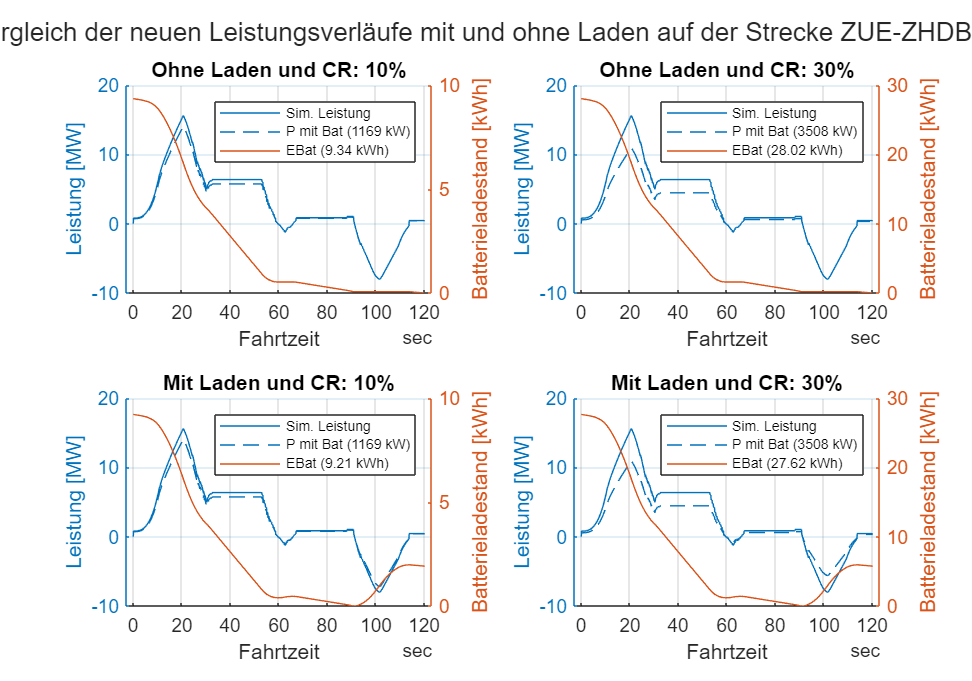

% Deckungsgrade die dargestellt werden sollen:
CRplot = [10, 30];
posCR1 = find(CR == CRplot(1));
posCR2 = find(CR == CRplot(2));
% Angabe der Strecke:
fnStr = fieldnames(BatDimCont);
n = 1;
fnStr(n);

f1 = figure();
t = tiledlayout(2,2);
%t.TileSpacing = 'compact';
%t.Padding = 'compact';
set(gcf, 'units', 'centimeters', 'position', [0,0,20,14])

nexttile
hold on
yyaxis left
plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).Leistung/1000)
plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).("LeistungNeu" + string(CRplot(1)) + "Prozent")/1000)
ylabel('Leistung [MW]')
xlabel('Fahrtzeit')
yyaxis right
plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).("EnergieBat" + string(CRplot(1)) + "Prozent"))
ylabel('Batterieladestand [kWh]')
title('Ohne Laden und CR: ' + string(CRplot(1)) + '%')
legend('Sim. Leistung', 'P mit Bat (' + string(round(BatDimParametersCont.(fnStr{n}).PBat(posCR1,1))) + ' kW)', 'EBat (' + string(round(BatDimParametersCont.(fnStr{n}).EBat(posCR1,1),2)) + ' kWh)', 'FontSize', 7)             
grid()
hold off

nexttile
hold on
yyaxis left
plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).Leistung/1000)
plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).("LeistungNeu" + string(CRplot(2)) + "Prozent")/1000)
ylabel('Leistung [MW]')
xlabel('Fahrtzeit')
yyaxis right
plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).("EnergieBat" + string(CRplot(2)) + "Prozent"))
ylabel('Batterieladestand [kWh]')
title('Ohne Laden und CR: ' + string(CRplot(2)) + '%')
legend('Sim. Leistung', 'P mit Bat (' + string(round(BatDimParametersCont.(fnStr{n}).PBat(posCR2,1))) + ' kW)', 'EBat (' + string(round(BatDimParametersCont.(fnStr{n}).EBat(posCR2,1),2)) + ' kWh)', 'FontSize', 7)  
grid()
hold off

nexttile
hold on
yyaxis left
plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).Leistung/1000)
plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).("LeistungNeu" + string(CRplot(1)) + "ProzentRech")/1000)
ylabel('Leistung [MW]')
xlabel('Fahrtzeit')
yyaxis right
plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).("EnergieBat" + string(CRplot(1)) + "ProzentRech"))
ylabel('Batterieladestand [kWh]')
title('Mit Laden und CR: ' + string(CRplot(1)) + '%')
legend('Sim. Leistung', 'P mit Bat (' + string(round(BatDimParametersCont.(fnStr{n}).PBat(posCR1,2))) + ' kW)', 'EBat (' + string(round(BatDimParametersCont.(fnStr{n}).EBat(posCR1,2),2)) + ' kWh)', 'FontSize', 7)  
grid()
hold off

nexttile
hold on
yyaxis left
plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).Leistung/1000)
plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).("LeistungNeu" + string(CRplot(2)) + "ProzentRech")/1000)
ylabel('Leistung [MW]')
xlabel('Fahrtzeit')
yyaxis right
plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).("EnergieBat" + string(CRplot(2)) + "ProzentRech"))
ylabel('Batterieladestand [kWh]')
title('Mit Laden und CR: ' + string(CRplot(2)) + '%')
legend('Sim. Leistung', 'P mit Bat (' + string(round(BatDimParametersCont.(fnStr{n}).PBat(posCR2,2))) + ' kW)', 'EBat (' + string(round(BatDimParametersCont.(fnStr{n}).EBat(posCR2,2),2)) + ' kWh)', 'FontSize', 7)  
grid()
hold off

title(t, 'Vergleich der neuen Leistungsverläufe mit und ohne Laden auf der Strecke ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's')

% speichern der plots
savename = 'Leistungsverläufe_mit_und_ohne_Laden_der_Batterie_' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + '_' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's';
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Cont\Vergleich_Leistung_Kapazität_mit_und_ohne_Laden', savename +'.png');
exportgraphics(f1, filename, 'Resolution',300)

## 1.7.) Verlauf der neuen Leistung und Batterieladestand mit kontinuierlichem Ansatz für ausgewählte Deckungsgrade

% Deckungsgrade die dargestellt werden sollen:
CRplot = 20;
posCR1 = find(CR == CRplot);
% Angabe der Strecke:
fnStr = fieldnames(BatDimCont);
n = 8;
fnStr(n);

f1 = figure();
t = tiledlayout(2,1);
%t.TileSpacing = 'compact';
%t.Padding = 'compact';
set(gcf, 'units', 'centimeters', 'position', [0,0,20,14])

nexttile
hold on
yyaxis left
plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).Leistung/1000)
plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).("LeistungNeu" + string(CRplot) + "Prozent")/1000)
ylabel('Leistung [MW]')
xlabel('Fahrtzeit')
yyaxis right
plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).("EnergieBat" + string(CRplot) + "Prozent"))
ylabel('Energie [kWh]')
title('Vergleich der neuen Leistungsverläufe mit und ohne Laden auf der Strecke ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's')
subtitle('Ohne Laden und CR: ' + string(CRplot) + '%')
legend('Sim. Leistung', 'P mit Bat (' + string(round(BatDimParametersCont.(fnStr{n}).PBat(posCR1,1))) + ' kW)', 'EBat (' + string(round(BatDimParametersCont.(fnStr{n}).EBat(posCR1,1),2)) + ' kWh)', 'FontSize', 6)             
grid()
hold off

nexttile
hold on
yyaxis left
plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).Leistung/1000)
plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).("LeistungNeu" + string(CRplot) + "ProzentRech")/1000)
ylabel('Leistung [MW]')
xlabel('Fahrtzeit')
yyaxis right
plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).("EnergieBat" + string(CRplot) + "ProzentRech"))
ylabel('Energie [kWh]')
subtitle('Mit Laden und CR: ' + string(CRplot) + '%')
legend('Sim. Leistung', 'P mit Bat (' + string(round(BatDimParametersCont.(fnStr{n}).PBat(posCR1,2))) + ' kW)', 'EBat (' + string(round(BatDimParametersCont.(fnStr{n}).EBat(posCR1,2),2)) + ' kWh)', 'FontSize', 6)  
grid()
hold off

% speichern der plots
% savename = 'Leistungsverläufe_mit_und_ohne_Laden_der_Batterie_Double' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + '_' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's';
% filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Cont\Vergleich_Leistung_Kapazität_mit_und_ohne_Laden', savename +'.png');
% exportgraphics(f1, filename, 'Resolution',300)

## 1.8.) Verlauf der neuen Leistung und Batterieladestand mit kontinuierlichem Ansatz für alle Deckungsgrade


% Angabe der Strecke:
fnStr = fieldnames(BatDimCont);

for n = 1:numel(fnStr)

    for k = 1:length(CR)

        f1 = figure();
        t = tiledlayout(2,1);
        %t.TileSpacing = 'compact';
        %t.Padding = 'compact';
        set(gcf, 'units', 'centimeters', 'position', [0,0,20,14])

        nexttile
        hold on
        yyaxis left
        plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).Leistung/1000)
        plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).("LeistungNeu" + string(CR(k)) + "Prozent")/1000)
        ylabel('Leistung [MW]')
        xlabel('Fahrtzeit')
        yyaxis right
        plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).("EnergieBat" + string(CR(k)) + "Prozent"))
        ylabel('Energie [kWh]')
        title('Vergleich der neuen Leistungsverläufe mit und ohne Laden auf der Strecke ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's')
        subtitle('Ohne Laden und CR: ' + string(CR(k)) + '%')
        legend('Sim. Leistung', 'P mit Bat (' + string(round(BatDimParametersCont.(fnStr{n}).PBat(k,1))) + ' kW)', 'EBat (' + string(round(BatDimParametersCont.(fnStr{n}).EBat(k,1),2)) + ' kWh)', 'FontSize', 6)
        grid()
        hold off

        nexttile
        hold on
        yyaxis left
        plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).Leistung/1000)
        plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).("LeistungNeu" + string(CR(k)) + "ProzentRech")/1000)
        ylabel('Leistung [MW]')
        xlabel('Fahrtzeit')
        yyaxis right
        plot(BatDimCont.(fnStr{n}).time, BatDimCont.(fnStr{n}).("EnergieBat" + string(CR(k)) + "ProzentRech"))
        ylabel('Energie [kWh]')
        subtitle('Mit Laden und CR: ' + string(CR(k)) + '%')
        legend('Sim. Leistung', 'P mit Bat (' + string(round(BatDimParametersCont.(fnStr{n}).PBat(k,2))) + ' kW)', 'EBat (' + string(round(BatDimParametersCont.(fnStr{n}).EBat(k,2),2)) + ' kWh)', 'FontSize', 6)
        grid()
        hold off

        % speichern der plots
        savename = 'CR' + string(CR(k)) + 'Leistungsverläufe_mit_und_ohne_Laden_der_Batterie' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + '_' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's';
        filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Cont\Vergleich_Leistung_Kapazität_mit_und_ohne_Laden', savename +'.png');
        exportgraphics(f1, filename, 'Resolution',300)
    end
end

## 1.9.) Maximale Batterieparameter für jede der vier Strecken (Kontinuierlich)

label = string(CR);


f1 = figure();

set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
bar(BDCont.EBatOhneLaden')
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
ylabel('Batteriekapazität [kWh]')
legend('ZUE-ZHDB', 'ZHDB-ZUE', 'ZUE-ZSTH', 'ZSTH-ZUE', 'location', 'northwest')
title('Benötigte maximale Batteriekapazitäten jeder Strecke')
subtitle('Kontinuierliche Auslegemethode ohne Laden')
grid()
% speichern der plots
savename = "Max_Batteriekapazitäten_ohne_Laden";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Cont\Max_Batterieparameter_aller_Strecken', savename +'.png');
exportgraphics(f1, filename, 'Resolution',300)

f1 = figure();
set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
bar(BDCont.EBatMitLaden')
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
ylabel('Batteriekapazität [kWh]')
legend('ZUE-ZHDB', 'ZHDB-ZUE', 'ZUE-ZSTH', 'ZSTH-ZUE', 'location', 'northwest')
title('Benötigte maximale Batteriekapazitäten jeder Strecke')
subtitle('Kontinuierliche Auslegemethode mit Laden')
grid()
% speichern der plots
savename = "Max_Batteriekapazitäten_mit_Laden";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Cont\Max_Batterieparameter_aller_Strecken', savename +'.png');
exportgraphics(f1, filename, 'Resolution',300)


f1 = figure();
set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
bar(BDCont.PBatOhneLaden')
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
ylabel('Batterieleistung [kW]')
legend('ZUE-ZHDB', 'ZHDB-ZUE', 'ZUE-ZSTH', 'ZSTH-ZUE', 'location', 'northwest')
title('Benötigte maximale Batterieleistungen jeder Strecke')
subtitle('Kontinuierliche Auslegemethode ohne Laden')
grid()
% speichern der plots
savename = "Max_Batterieleistungen_ohne_Laden";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Cont\Max_Batterieparameter_aller_Strecken', savename +'.png');
exportgraphics(f1, filename, 'Resolution',300)

f1 = figure();
set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
bar(BDCont.PBatMitLaden')
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
ylabel('Batterieleistung [kW]')
legend('ZUE-ZHDB', 'ZHDB-ZUE', 'ZUE-ZSTH', 'ZSTH-ZUE', 'location', 'northwest')
title('Benötigte maximale Batterieleistungen jeder Strecke')
subtitle('Kontinuierliche Auslegemethode mit Laden')
grid()
% speichern der plots
savename = "Max_Batterieleistungen_mit_Laden";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Cont\Max_Batterieparameter_aller_Strecken', savename +'.png');
exportgraphics(f1, filename, 'Resolution',300)


## 1.9.1) Multiplots Maximale Batterieparameter für jede der vier Strecken

label = string(CR);

f1 = figure();
tiledlayout(2,1);
set(gcf, 'units', 'centimeters', 'position', [0,0,20,14])

nexttile
bar(BDCont.EBatOhneLaden')
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
ylabel('Batteriekapazität [kWh]')
legend('ZUE-ZHDB', 'ZHDB-ZUE', 'ZUE-ZSTH', 'ZSTH-ZUE', 'location', 'northwest')
title('Benötigte maximale Batteriekapazitäten jeder Strecke')
subtitle('Kontinuierliche Auslegemethode ohne Laden')
grid()

nexttile
bar(BDCont.EBatMitLaden')
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
ylabel('Batteriekapazität [kWh]')
legend('ZUE-ZHDB', 'ZHDB-ZUE', 'ZUE-ZSTH', 'ZSTH-ZUE', 'location', 'northwest')
subtitle('Kontinuierliche Auslegemethode mit Laden')
grid()
% speichern der plots
savename = "Multiplot_Max_Batteriekapazitäten";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Cont\Max_Batterieparameter_aller_Strecken', savename +'.png');
exportgraphics(f1, filename, 'Resolution',300)

f1 = figure();
tiledlayout(2,1);
set(gcf, 'units', 'centimeters', 'position', [0,0,20,14])

nexttile
bar(BDCont.PBatOhneLaden')
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
ylabel('Batterieleistung [kW]')
legend('ZUE-ZHDB', 'ZHDB-ZUE', 'ZUE-ZSTH', 'ZSTH-ZUE', 'location', 'northwest')
title('Benötigte maximale Batterieleistungen jeder Strecke')
subtitle('Kontinuierliche Auslegemethode ohne Laden')
grid()

nexttile
bar(BDCont.PBatMitLaden')
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
ylabel('Batterieleistung [kW]')
legend('ZUE-ZHDB', 'ZHDB-ZUE', 'ZUE-ZSTH', 'ZSTH-ZUE', 'location', 'northwest')
subtitle('Kontinuierliche Auslegemethode mit Laden')
grid()
% speichern der plots
savename = "Multiplot_Max_Batterieleistungen";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Cont\Max_Batterieparameter_aller_Strecken', savename +'.png');
exportgraphics(f1, filename, 'Resolution',300)

## 1.10.) Verlauf der Gesamtleistung mit kontinuierlichem Batterieeinsatz

time = seconds(0:0.1:86399.9)'; 
time.Format = 'hh:mm:ss.S';
figure
tiledlayout(2,1);
set(gcf, 'units', 'centimeters', 'position', [0,0,20,14])

nexttile
hold on
plot(time, P_totSim/1000)
plot(time, P_totSimBatDimCont(:,5)/1000)
plot(time, P_totSimBatDimCont(:,9)/1000)
xtickformat('hh:mm')
xlabel('Uhrzeit')
ylabel('Leistung [MW]')
title('Vergleich der simulierten mit der neuen Gesamtleistung im Speisepunkt Museumstrasse')
subtitle('Kontinuierlicher Batterieeinsatz ohne Laden der Batterie')
legend('Sim. Leistung', 'CR: 15%', 'CR: 40%')
grid()
hold off

nexttile
hold on
plot(time(215000:225000), P_totSim(215000:225000)/1000)
plot(time(215000:225000), P_totSimBatDimCont(215000:225000,5)/1000)
plot(time(215000:225000), P_totSimBatDimCont(215000:225000,9)/1000)
%plot(time(285000:295000), P_totSim(285000:295000)/1000)
xtickformat('hh:mm')
%xticks(time(285000):minutes(5):time(295000))
xticks(time(215000):minutes(5):time(225000))
xlabel('Uhrzeit')
ylabel('Leistung [MW]')
grid()
hold off

% speichern der plots
savename = "Vergleich_Gesamtleistung_mit_und_ohne_Kont_Batterieeinsatz_Zoomed";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Cont\Gesamtleistung_mit_kontinuierlichem_Batterieeinsatz\', savename +'.png');
exportgraphics(gcf, filename, 'Resolution',300)


figure
set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
hold on
plot(time(215000:225000), P_totSim(215000:225000)/1000)
plot(time(215000:225000), P_totSimBatDimCont(215000:225000,8)/1000)
plot(time(215000:225000), P_totSimBatDimCont(215000:225000,19)/1000)
xtickformat('hh:mm')
xticks(time(215000):minutes(5):time(225000))
xlabel('Uhrzeit')
ylabel('Leistung [MW]')
legend('Sim. Leistung', 'CR: 30% ohne Laden', 'CR: 30% mit Laden')
title('Vergleich der simulierten mit der neuen Gesamtleistung im Speisepunkt Museumstrasse')
subtitle('Kontinuierlicher Batterieeinsatz mit und ohne Laden der Batterie')
grid()
hold off
% speichern der plots
savename = "Vergleich_Gesamtleistung_mit_Kont_Batterieeinsatz_Zoomed_mit_ohne_Laden";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Cont\Gesamtleistung_mit_kontinuierlichem_Batterieeinsatz\', savename +'.png');
exportgraphics(gcf, filename, 'Resolution',300)


## 1.11.) Vergleich der 8 min Mittelwerte mit den Verläufen der Gesamtleistung (Kontinuierlich)

P_totSimMean = zeros(288,1);

n = 1;
for i = 1:3000:864000
    if (i < 4800)
        P_totSimMean(n,1) = mean(P_totSim(1:i));
    else
        P_totSimMean(n,1) = mean(P_totSim(i-4800:i));
    end
    n = n + 1;
end

P_totSimBatDimContMean = zeros(288,length(CR));


for k = 1:length(CR)*2
    n = 1;
    for i = 1:3000:864000
        if (i < 4800)
            P_totSimBatDimContMean(n,k) = mean(P_totSimBatDimCont(1:i,k));
        else
            P_totSimBatDimContMean(n,k) = mean(P_totSimBatDimCont(i-4800:i,k));
        end
        n = n + 1;
    end
end


% Erstellung eines Zeitarrays für die 5 min. Mittelwerte (alle 5 Min.)
time2 = seconds(0:300:86400-300);
time2.Format = 'hh:mm:ss.S';

for n = 1:length(CR)
    figure
    set(gcf, 'units', 'centimeters', 'position', [0,0,20,14])
    tiledlayout(2,2)


    nexttile([1 2])
    %nexttile
    hold on
    % Montag:
    plot(time2, Meas.P8minMittelMW(1:length(time2)))
    % Sonntag:
    %plot(time2, Meas.P8minMittelMW(1729:2016))


    plot(time2, P_totSimMean/1000)
    plot(time2, P_totSimBatDimContMean(:,n)/1000)
    plot(time2, P_totSimBatDimContMean(:,n+length(CR))/1000)
    title('Vergleich der Messwerte mit dem Simulierten Leistungsverlauf mit Batterieeinsatz')
    subtitle('Kontinuierlicher Batterieeinsatz mit und ohne Laden')
    grid()
    legend('Gemessene Leistung', 'Sim. Leistung', 'CR: ' + string(CR(n)) + '% ohne Laden', 'CR: ' + string(CR(n)) + '% mit Laden' , 'Location', 'northwest', 'FontSize', 8)
    xlabel('Uhrzeit')
    ylabel('Leistung [MW]')
    xtickformat('hh:mm')
    hold off

    nexttile
    hold on
    % Montag:
    plot(time2(70:115), Meas.P8minMittelMW(70:115))
    plot(time2(70:115), P_totSimMean(70:115)/1000)
    % Sonntag:
    %plot(time2(70:115), Meas.P8minMittelMW(70:115))
    plot(time2(70:115), P_totSimBatDimContMean(70:115,n)/1000)
    plot(time2(70:115), P_totSimBatDimContMean(70:115,n+length(CR))/1000)
    subtitle('06:00 - 09:00 Uhr')
    grid()
    xlabel('Uhrzeit')
    ylabel('Leistung [MW]')
    xtickformat('hh:mm')
    hold off

    nexttile
    hold on
    plot(time2(190:235), Meas.P8minMittelMW((190:235)))
    plot(time2(190:235), P_totSimMean(190:235)/1000)

    plot(time2(190:235), P_totSimBatDimContMean(190:235,n)/1000)
    plot(time2(190:235), P_totSimBatDimContMean(190:235,n+length(CR))/1000)
    subtitle('16:00 - 19:00 Uhr')
    grid()
    xlabel('Uhrzeit')
    ylabel('Leistung [MW]')
    xtickformat('hh:mm')
    hold off

    % speichern der plots
    savename = "CR_" + string(CR(n)) + "_Vergleich_Messwerte_mit_Batterieeinsatz";
    filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Cont\MesswertVergleich\', savename +'.png');
    exportgraphics(gcf, filename, 'Resolution',300)
end


## 1.12.) Vergleich der Leistungsspitzen in der Echtzeitsimulation mit kontinuierlicher Methode

label = string(CR);
clearvars LastSpitzenCont;
for k = 1:length(CR)
    
    LastSpitzenCont(k,1) = max(P_totSimBatDimCont(:,k));
    LastSpitzenCont(k,2) = max(P_totSimBatDimCont(:,k+length(CR)));


end

% figure()
% set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
% bar(LastSpitzenCont/1000)
% yline(max(P_totSim)/1000, '-','max. Simulierte Leistungsspitze ohne Batterie')
% set(gca, 'xtick', 1:length(label), 'xticklabel', label)
% xlabel('Deckungsgrad [%]')
% ylabel('max. Leistungsspitze [MW]')
% ylim([0,max(P_totSim)/1000+5])
% legend('ohne Laden', 'mit Laden', 'location', 'southwest')
% title('Vergleich der Leistungsspitzen der Simulation mit und ohne Traktionsbatterie')
% subtitle('Kontinuierliche Methode')
% grid()

% speichern der plots
% savename = "Vergleich_der_Leistungsspitzen_mit_Kontinuierlichem_Ansatz";
% filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Cont\Analyse_Leistungsspitzen\', savename +'.png');
% exportgraphics(gcf, filename, 'Resolution',300)

LastSpitzenCont(:,1) = LastSpitzenCont(:,1)/1000;
LastSpitzenCont(:,2) = LastSpitzenCont(:,2)/1000;
LastSpitzenCont(:,3) = (1 - LastSpitzenCont(:,1)/(max(P_totSim)/1000))*100;
LastSpitzenCont(:,4) = (1 - LastSpitzenCont(:,2)/(max(P_totSim)/1000))*100;


## 1.13.) Vergleich der Leistungsspitzen mit den 8 Min. Mittelwerten mit kontinuierlicher Methode

label = string(CR);
clearvars LastSpitzenContMean;
for k = 1:length(CR)
    
    LastSpitzenContMean(k,1) = max(P_totSimBatDimContMean(:,k));
    LastSpitzenContMean(k,2) = max(P_totSimBatDimContMean(:,k+length(CR)));


end

figure()
set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
bar(LastSpitzenContMean/1000)
yline(max(P_totSimMean)/1000, '-','max. Simulierte Leistungsspitze ohne Batterie')
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
ylabel('max. Leistungsspitze [MW]')
ylim([0,max(P_totSimMean)/1000+2])
legend('ohne Laden', 'mit Laden', 'location', 'northwest')
title('Vergleich der Leistungsspitzen der 8 Min. Mittelwerte mit und ohne Traktionsbatterie')
subtitle('Kontinuierliche Methode')
grid()

% speichern der plots
savename = "Vergleich_der_Leistungsspitzen_der_8Min_Mittelwerte_mit_Kontinuierlichem_Ansatz";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Cont\Analyse_Leistungsspitzen\', savename +'.png');
exportgraphics(gcf, filename, 'Resolution',300)

LastSpitzenContMean(:,1) = LastSpitzenContMean(:,1)/1000;
LastSpitzenContMean(:,2) = LastSpitzenContMean(:,2)/1000;
LastSpitzenContMean(:,3) = (1 - LastSpitzenContMean(:,1)/(max(P_totSimMean)/1000))*100;
LastSpitzenContMean(:,4) = (1 - LastSpitzenContMean(:,2)/(max(P_totSimMean)/1000))*100;